## 1.1) Plotting signals 

warning('off');
clear 
[sonata,fs] = audioread("sonata.mp3");
fprintf('Sampling Frequency : %d',fs);

Sampling Frequency : 44100

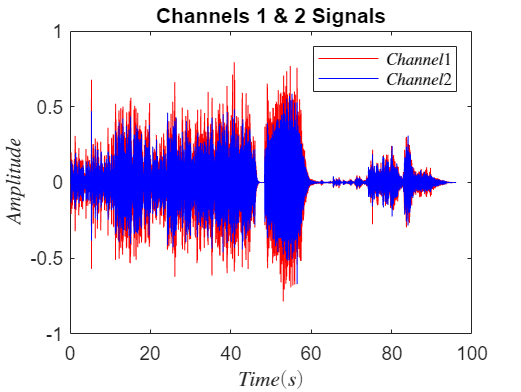

ch1=sonata(:,1);
ch2=sonata(:,2);
t=0:1/fs:(length(sonata)-1)/fs;
plot(t,ch1,'red',t,ch2,'blue');
xlabel ('$Time(s)$','Interpreter','latex')
ylabel ('$Amplitude$','Interpreter','latex')
title ('Channels 1 & 2 Signals')
legend('$Channel 1$','$Channel 2$','Interpreter','latex');

## 1.2) Fourier Transform of channels

N=length(ch1);
f=-fs/2:fs/N:fs/2-fs/N;
FT_ch1=fftshift(fft(ch1));
FT_ch2=fftshift(fft(ch2));
plot(f,abs(FT_ch1/N),"red");
hold on 
plot(f,abs(FT_ch2/N),"blue");
xlabel ('$Freaquency(Hz)$','Interpreter','latex')
ylabel ('$Amplitude$','Interpreter','latex')
title ('Fourier Transform of Channels 1 & 2 ')
legend('$F[ch1]$','$F[ch2]$','Interpreter','latex');
hold off

## Power Spectrum of Channel 1

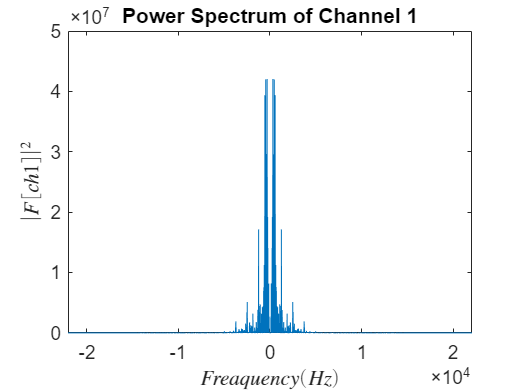

power=abs(FT_ch1).^2;
plot(f,real(power));
xlabel ('$Freaquency(Hz)$','Interpreter','latex')
ylabel ('$|F[ch1]|^2$','Interpreter','latex')
title ('Power Spectrum of Channel 1')

## 1.3) Spectrogram

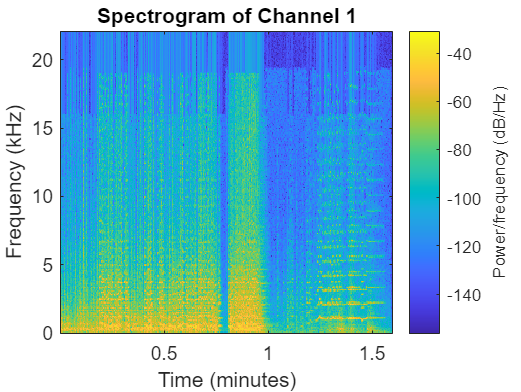

spectrogram(ch1,1000,50,500,fs,'yaxis');
title('Spectrogram of Channel 1')

## 1.5) Spectrogram Arguments

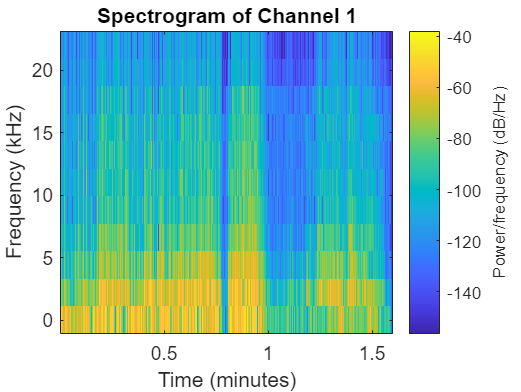

spectrogram(ch1,100,50,20,fs,'yaxis');
title('Spectrogram of Channel 1')

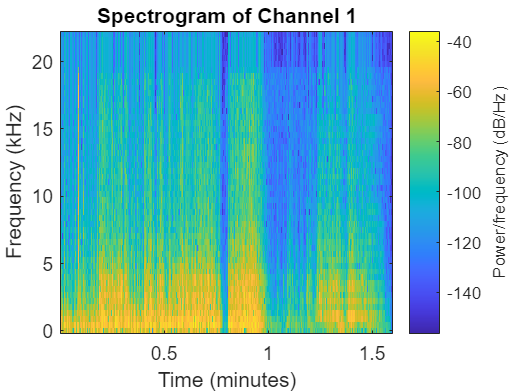

spectrogram(ch1,100,5,100,fs,'yaxis');
title('Spectrogram of Channel 1')

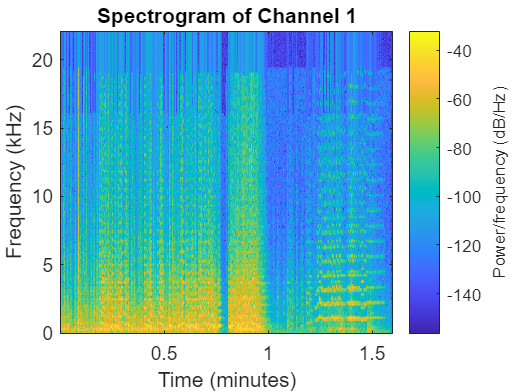

spectrogram(ch1,500,50,500,fs,'yaxis');
title('Spectrogram of Channel 1')

spectrogram(ch1,1000,50,500,fs,'yaxis');
title('Spectrogram of Channel 1')